# HW4 Program Assignment

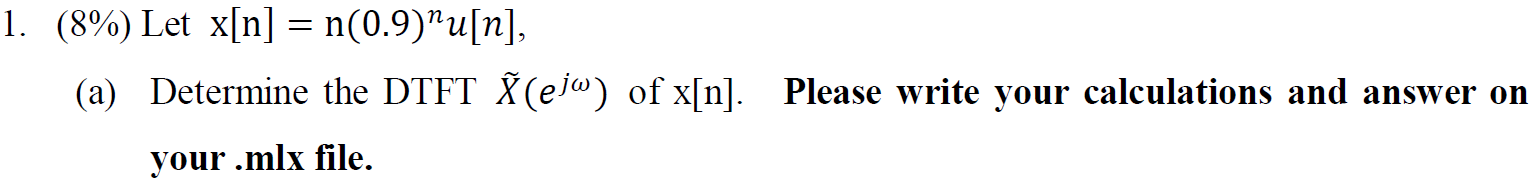

                
$$a^n u\left\lbrack n\right\rbrack \to \frac{1}{1-{\mathrm{ae}}^{-j\omega } }$$


                
$$\mathrm{nx}\left\lbrack n\right\rbrack \to j\frac{d}{d\omega }X\left(e^{j\omega } \right)$$


                So, ${\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack \to \frac{1}{1-0\ldotp 9e^{-j\omega } }$

                
$${n\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack \to \frac{0\ldotp 9e^{-j\omega } }{{\left(1-0\ldotp 9e^{-j\omega } \right)}^2 }$$


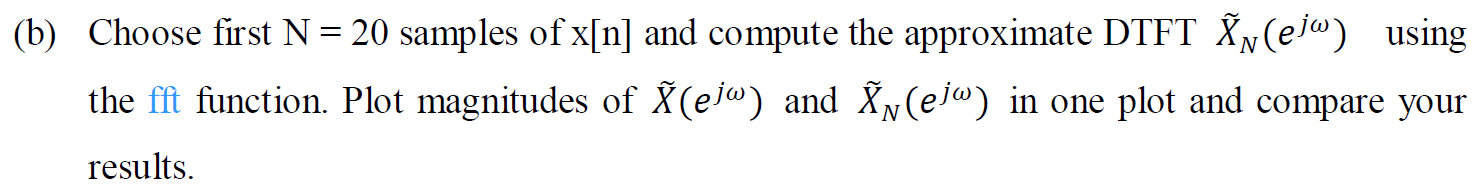

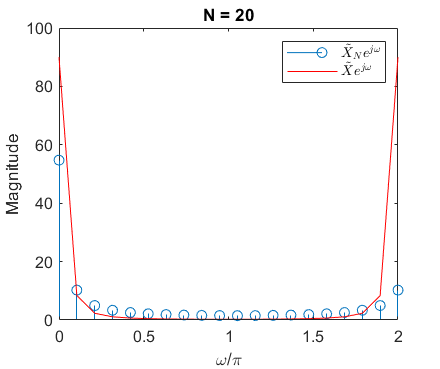

N = 20;
w = linspace(0, 2*pi, N);
n = 0:N-1;
xn = n.*(0.9.^n);
Xn = fft(xn);
stem(w/pi, abs(Xn));
hold on
X = 0.9*exp(-1j*w)./((1 - 0.9*exp(-1j*w)).^2);
plot(w/pi, abs(X), 'r');
le = legend('$\tilde{X}_{N}e^{j\omega}$', '$\tilde{X}e^{j\omega}$');
set(le, 'interpreter', 'latex');
xlabel('\omega/\pi');
ylabel('Magnitude');
title('N = 20');
hold off

### Compare:  $\overset{~}{X_N e^{j\omega } }$ and $\overset{~}{Xe^{j\omega } }$ is different at each $\omega$ value because sample point N = 20 is too few.

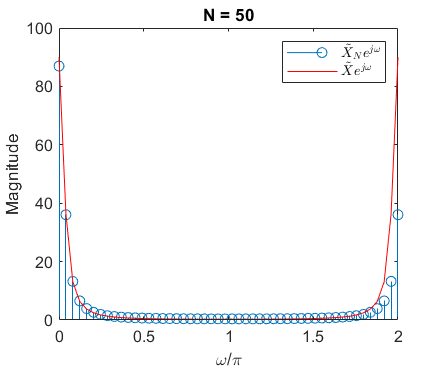

N = 50;
w = linspace(0, 2*pi, N);
n = 0:N-1;
xn = n.*(0.9.^n);
Xn = fft(xn);
stem(w/pi, abs(Xn));
hold on
X = 0.9*exp(-1j*w)./((1 - 0.9*exp(-1j*w)).^2);
plot(w/pi, abs(X), 'r');
le = legend('$\tilde{X}_{N}e^{j\omega}$', '$\tilde{X}e^{j\omega}$');
set(le, 'interpreter', 'latex');
xlabel('\omega/\pi');
ylabel('Magnitude');
title('N = 50');
hold off

### Compare: The difference $\overset{~}{X_N e^{j\omega } }$ and $\overset{~}{Xe^{j\omega } }$ narrows because the number of sample (N) increases.

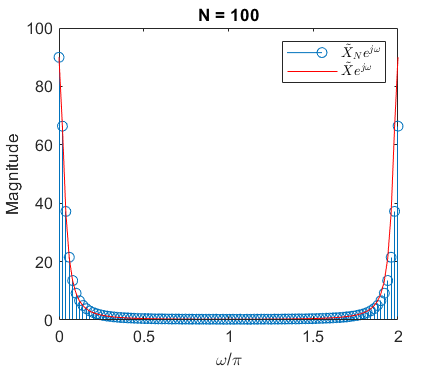

N = 100;
w = linspace(0, 2*pi, N);
n = 0:N-1;
xn = n.*(0.9.^n);
Xn = fft(xn);
stem(w/pi, abs(Xn));
hold on
X = 0.9*exp(-1j*w)./((1 - 0.9*exp(-1j*w)).^2);
plot(w/pi, abs(X), 'r');
le = legend('$\tilde{X}_{N}e^{j\omega}$', '$\tilde{X}e^{j\omega}$');
set(le, 'interpreter', 'latex');
xlabel('\omega/\pi');
ylabel('Magnitude');
title('N = 100');
hold off

### Compare: Now their difference has almost disappears as the sample point reaches 100. 

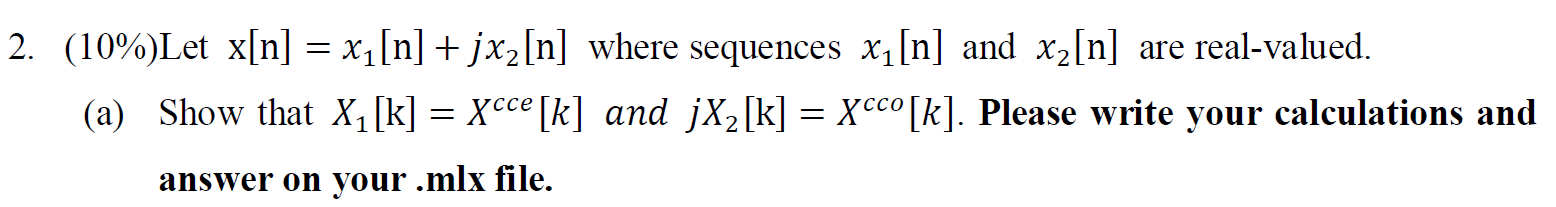

        $x^* \left\lbrack n\right\rbrack \to X^* \left\lbrack <-k>_N \right\rbrack$ (DFT)

        x[n] = $\frac{1}{2}$(x[n]$+x^* \left\lbrack n\right\rbrack$)+$\frac{1}{2}$(x[n]$-x^* \left\lbrack n\right\rbrack$) = $x_{1\left\lbrack \right.} \left\lbrack n\right\rbrack +{\mathrm{jx}}_2 \left\lbrack n\right\rbrack ,x_1 \left\lbrack n\right\rbrack =$ $\frac{1}{2}$(x[n]$+x^* \left\lbrack n\right\rbrack$) and $\;\;\;\;\;\;\;\;\;{\mathrm{jx}}_2 \left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack -x^* \left\lbrack n\right\rbrack \right)$

        Therefore, x[n]$\to \frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack <-k>_N \right\rbrack \right)+\frac{1}{2}\left(X\left\lbrack k\right\rbrack -X^* \left\lbrack <-k>_N \right\rbrack \right)$, $X_1 \left\lbrack k\right\rbrack =$$\frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack <-k>_N \right\rbrack \right)$, ${\;\;\;\;\;\;\;\;\mathrm{jX}}_2 \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack -X^* \left\lbrack <-k>_N \right\rbrack \right)$

         ${X_1 }^* \left\lbrack <-k>_N \right\rbrack$=$\frac{1}{2}{\left\lbrack X\left\lbrack <-k>_N \right\rbrack +X^* \left\lbrack k\right\rbrack \right\rbrack }^* =$$\frac{1}{2}\left(X^* \left\lbrack <-k>_N \right\rbrack +X\left\lbrack k\right\rbrack \right)=X_1 \left\lbrack k\right\rbrack$ By the definition, $X_1 \left\lbrack k\right\rbrack =X^{\mathrm{cce}} \left\lbrack k\right\rbrack$ 

        $-{{\mathrm{jX}}_2 }^* \left\lbrack <-k>_N \right\rbrack$=$-\frac{1}{2}{\left\lbrack X\left\lbrack <-k>_N \right\rbrack -X^* \left\lbrack k\right\rbrack \right\rbrack }^* =$$\frac{1}{2}\left({-X}^* \left\lbrack <-k>_N \right\rbrack +X\left\lbrack k\right\rbrack \right)={\mathrm{jX}}_2 \left\lbrack k\right\rbrack$ By the definition, ${\mathrm{jX}}_2 \left\lbrack k\right\rbrack =X^{\textrm{cco}} \left\lbrack k\right\rbrack$ 

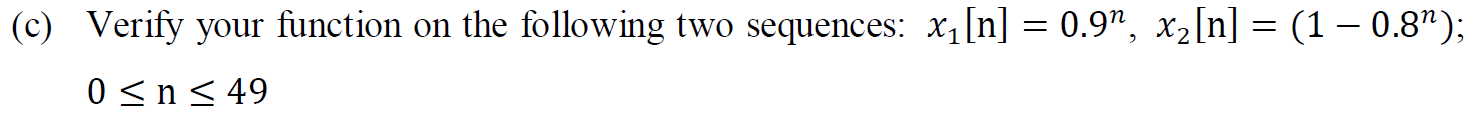

n = 0:49;
x1 = 0.9.^n;
x2 = 1-0.8.^n;
[X1, X2] = tworealDFTs(x1, x2);
round(fft(x1)) == round(X1)

ans = 1×50 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


round(fft(x2)) == round(X2)

ans = 1×50 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


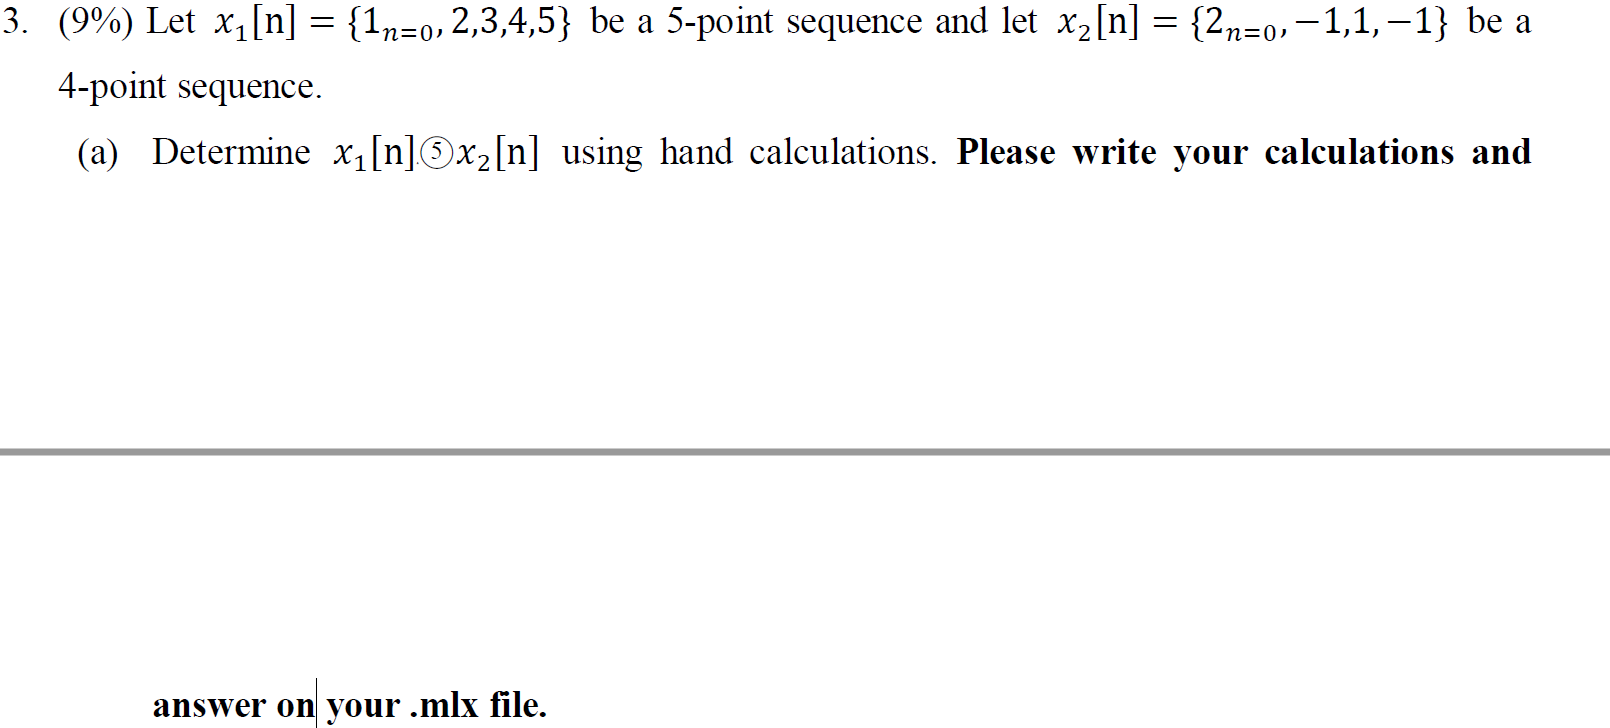

We should zero pad 1 zero on $x_2 \left\lbrack n\right\rbrack \;$to make it also have 5 points as $x_1 \left\lbrack n\right\rbrack$


$$\left\lbrack \begin{array}{ccccc}
2 & 0 & -1 & 1 & -1\\
-1 & 2 & 0 & -1 & 1\\
1 & -1 & 2 & 0 & -1\\
-1 & 1 & -1 & 2 & 0\\
0 & -1 & 1 & -1 & 2
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
1\\
2\\
3\\
4\\
5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-2\\
4\\
0\\
6\\
7
\end{array}\right\rbrack$$


x = [2 0 -1 1 -1; -1 2 0 -1 1;
    1 -1 2 0 -1; -1 1 -1 2 0;
    0 -1 1 -1 2];
y = [1 2 3 4 5]';
x*y

ans =     -2
     4
     0
     6
     7


x1 = [1 2 3 4 5];
x2 = [2 -1 1 -1 0];
y = circonv(x1.', x2.')

y =     -2
     4
     0
     6
     7


### The result is consistent with hand calculation.

x1 = [1 2 3 4 5];
x2 = [2 -1 1 -1 0];
X1 = fft(x1);
X2 = fft(x2);
Y = X1.*X2;
ifft(Y)

ans =    -2.0000    4.0000    0.0000    6.0000    7.0000


### The result is consistent with hand calculation.

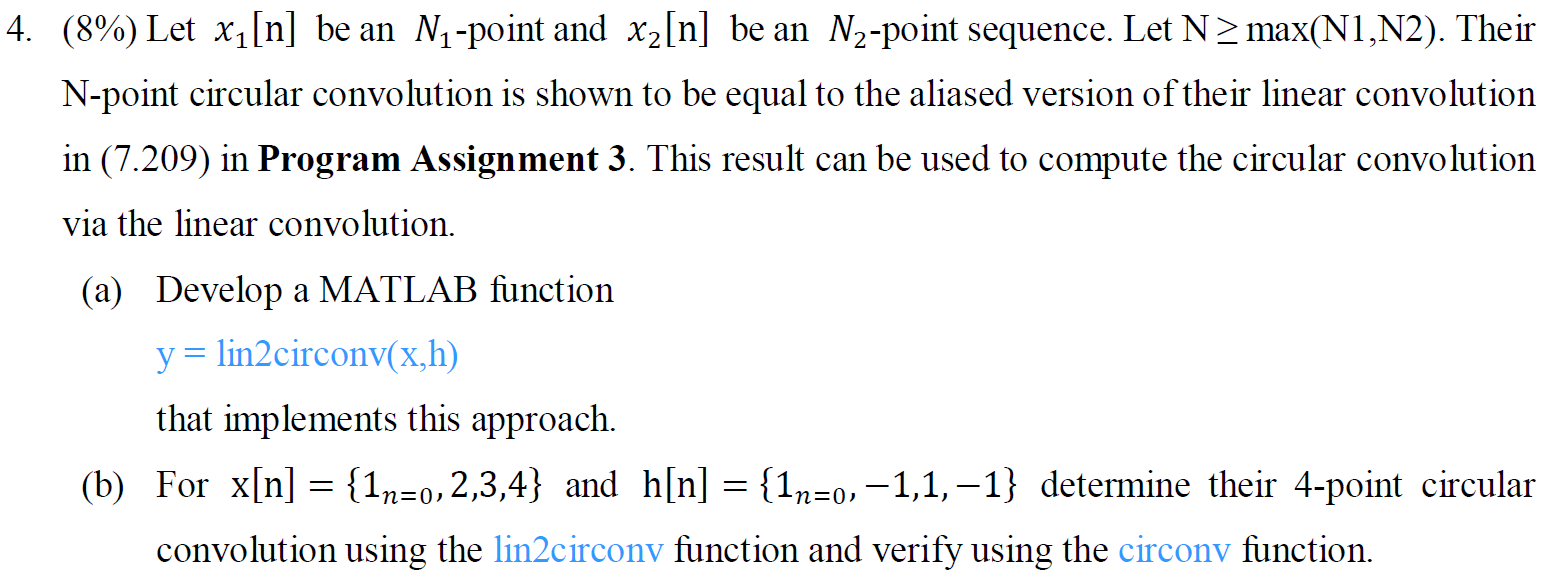

x = [1 2 3 4];
h = [1 -1 1 -1];
y_lin2 = lin2circonv(x, h)

y_lin2 =     -2     2    -2     2


y_circonv = circonv(x.', h.')

y_circonv =     -2
     2
    -2
     2


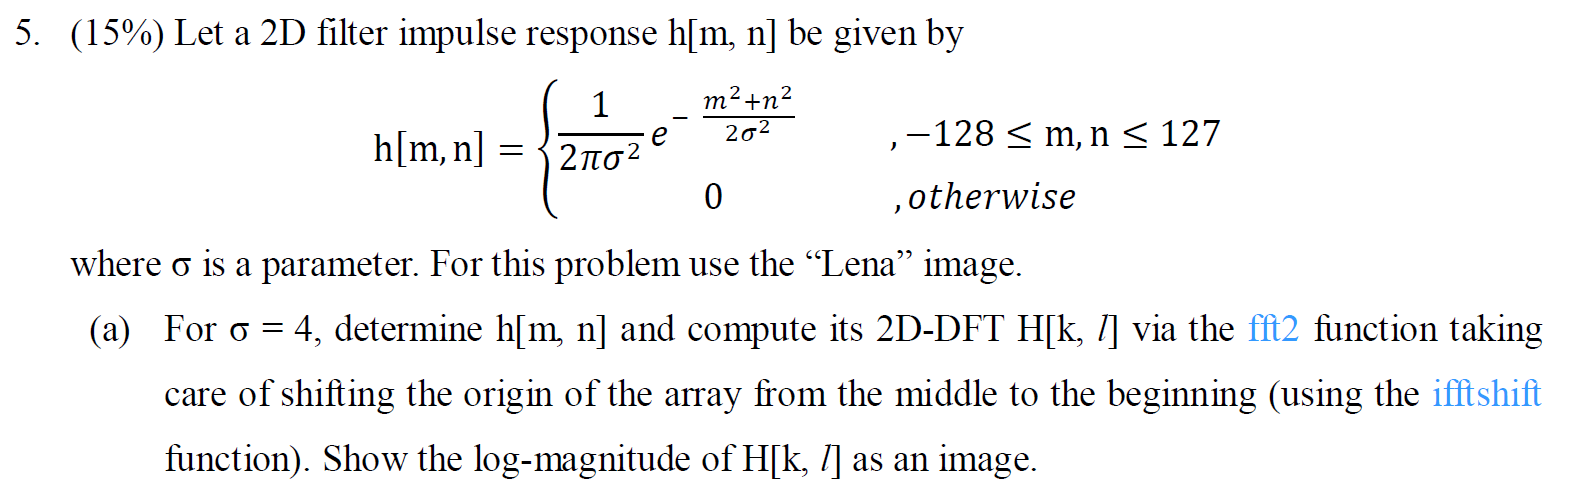

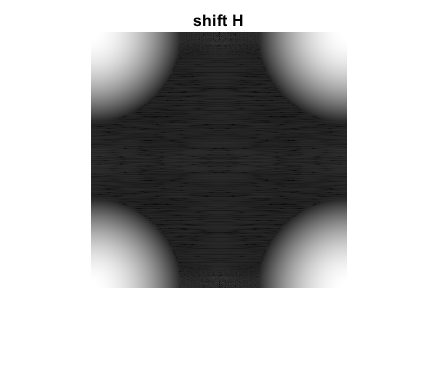

sigma = 4;
%imshow(lena)
m = -128:127;
n = -128:127;
h = 1/(2*pi*sigma^2)*exp(-(m'.^2+n.^2)/(2*sigma^2));
H_a = fft2(ifftshift(h));
imshow((log10(abs(H_a))), []);
title('shift H');

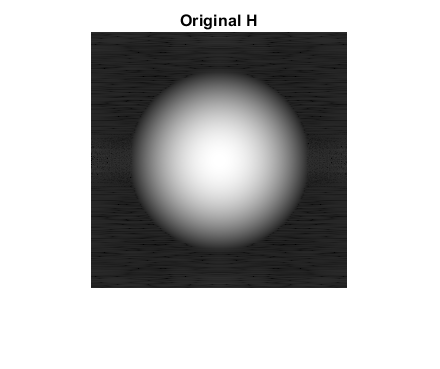

H_a_shift = ifftshift(H_a);
imshow((log10(abs(H_a_shift))), []);
title('Original H');

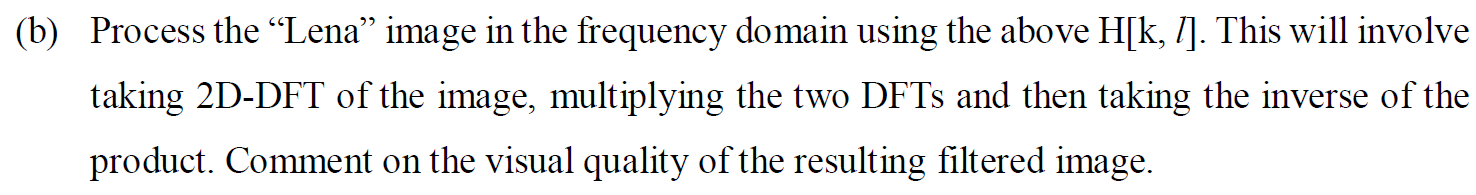

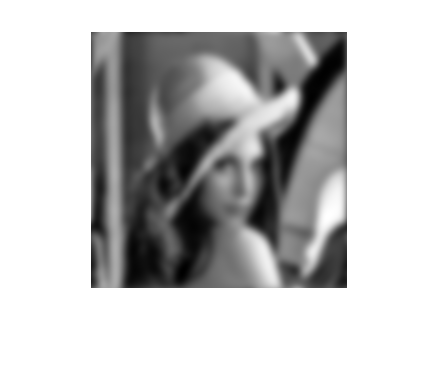

lena = imread('lena.jpg');
LENA = fft2(lena);
Y = LENA.*H_a;
y = (ifft2(Y));
imshow(y,[]);    %imshow: 灰階

### Comment: h[m, n] is Gaussian filter, which is a low-pass filter. After the image is filtered, its high frequency components disappear. It means that the image has lost its sharpness and become blur. And because low frequency components in a image means the slow change of color, which is usually large area and include most information of a image. So we can still see the  rough look of the image. 

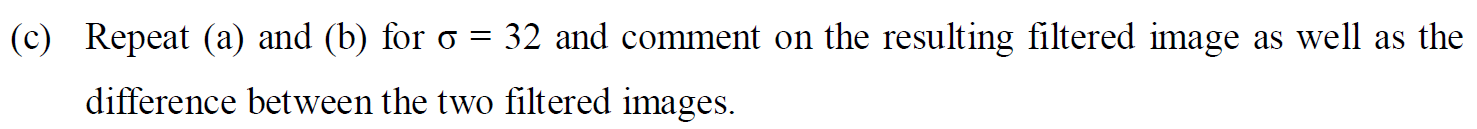

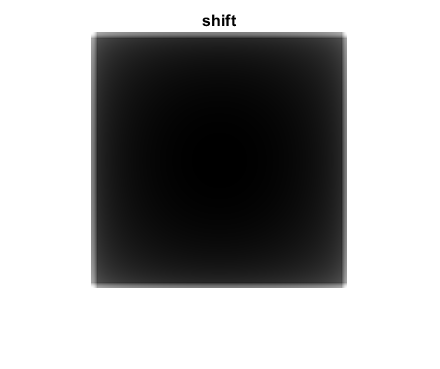

sigma = 32;
%imshow(lena)
m = -128:127;
n = -128:127;
h = 1/(2*pi*sigma^2)*exp(-(m'.^2+n.^2)/(2*sigma^2));
H_b = fft2(ifftshift(h));
imshow(log10(abs(H_b)), []);
title('shift');

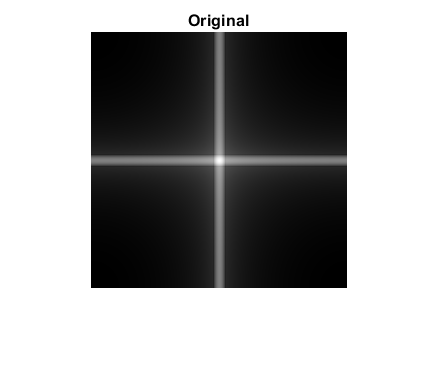

H_b_shift = ifftshift(H_b);
imshow(log10(abs(H_b_shift)), []);
title('Original');

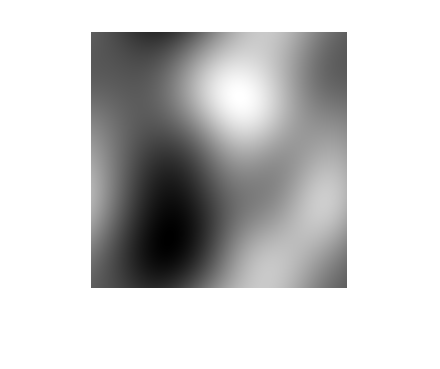

Y_b = LENA.*H_b;
y_b = (ifft2(Y_b));
imshow(y_b, []);

### Comment: $\sigma$ becomes larger means that the pass band of low pass filter becomes smaller. Therefore, very little information of the image is kept after applying filter. That's why we can barely understand what the filtered image is. 

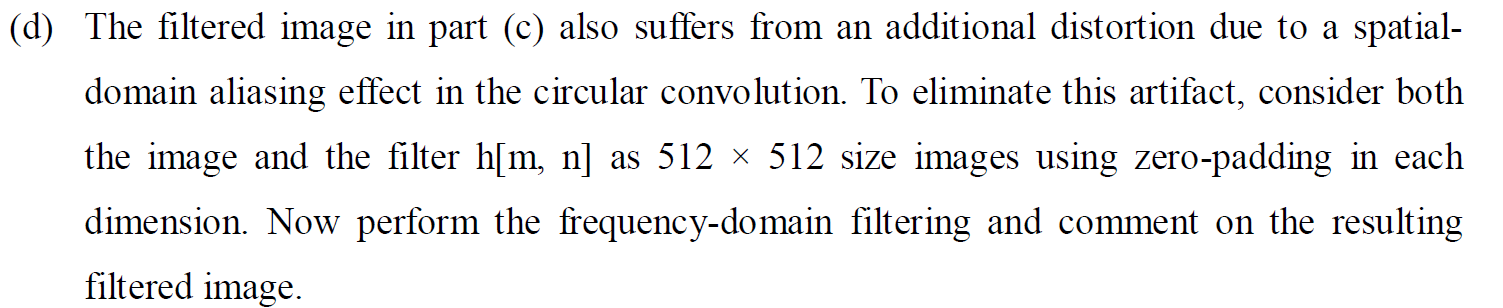

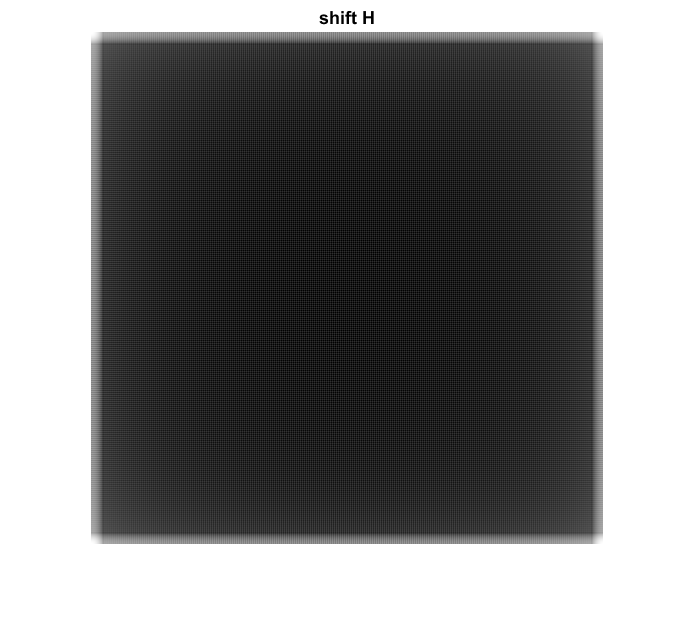

lena = imread('lena.jpg');
lena_pad = padarray(lena, [128, 128]);
LENA_pad = fft2(lena_pad);
h_pad = padarray(h, [128, 128]);
H_b_pad = fft2(ifftshift(h_pad));
imshow(log10(abs(H_b_pad)), []);
title('shift H');

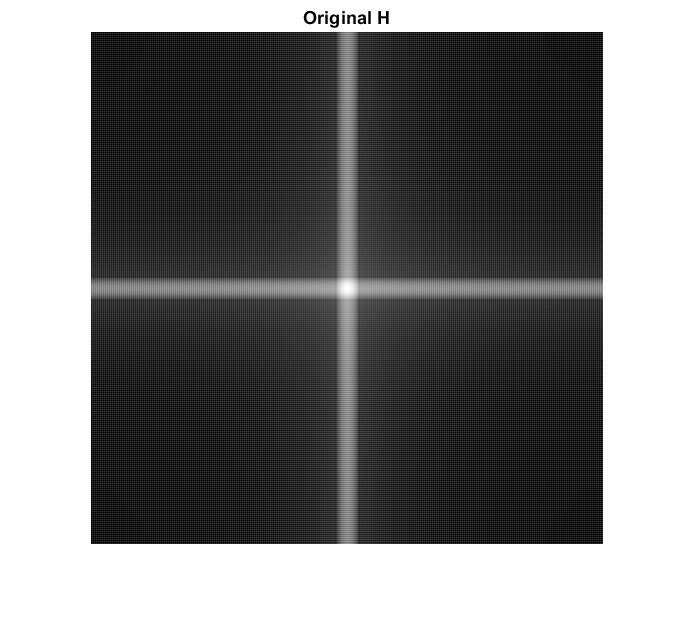

imshow(log10(abs(ifftshift(H_b_pad))), []);
title('Original H');

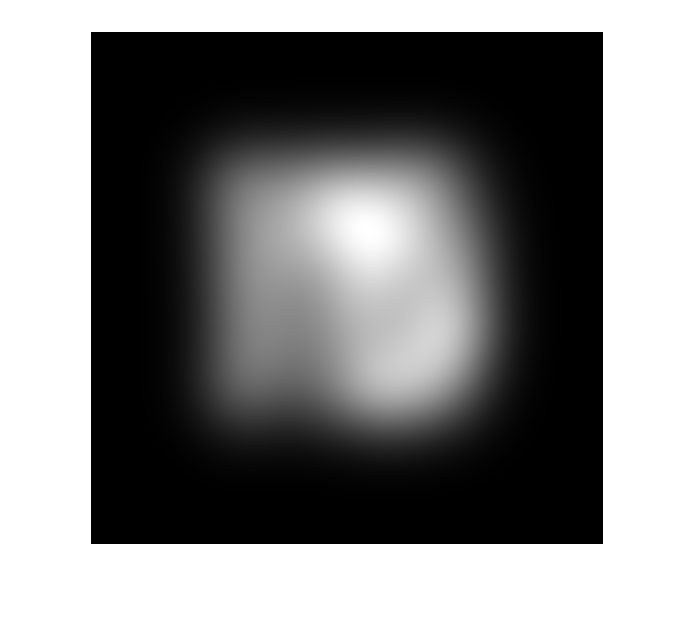

Y_b_pad = LENA_pad.*H_b_pad;
y_b_pad = ifft2(Y_b_pad);
imshow(y_b_pad, []);

### Comment: The filtered image is still blur as previous one. I believe it's because $\sigma$ = 32 is too large so that the pass band of low pass filter is too narrow, we are sill not able to see the filtered image clearly. 

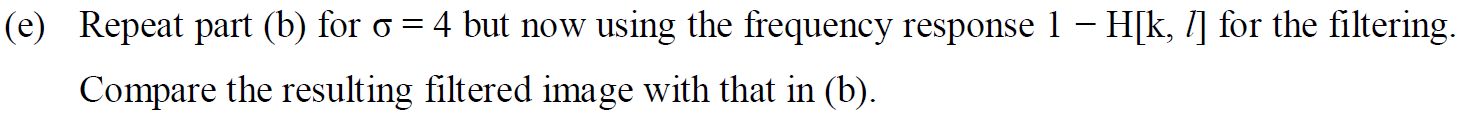

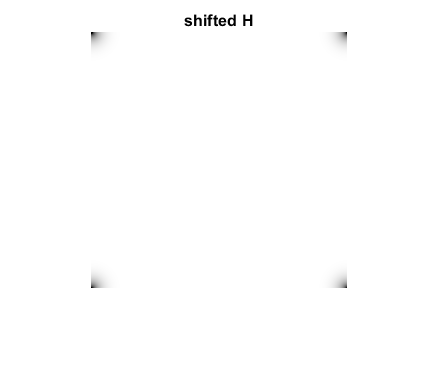

H_d = 1-H_a;
imshow(log10(abs(H_d)), []);
title('shifted H');

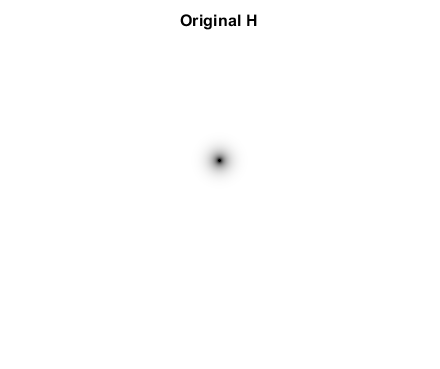

imshow(log10(abs(ifftshift(H_d))), []);
title('Original H');

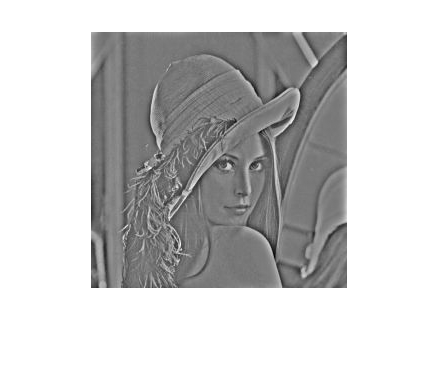

LENA = fft2(lena);
Y_d = LENA.*H_d;
y_d = ifft2(Y_d);
imshow(y_d, []);

### Comment: 1-H (H is low pass filter in part (a)) is a high pass filter. So the low frequency parts of a iamge has bee filterd out, which means that we can not see the color distribution of a image. And high frequency parts, the edge parts in a image (where color has dramatic change), are kept after filtering. Therefore, we can easily see the edge of the filterd image.